%% 7번 문제
clear; clc;

rng('default');
num_patients = 300;

% (a) 
avg_interarrival = 8;
interarrival_times = -avg_interarrival * log(rand(num_patients, 1));
arrival_times = cumsum(interarrival_times);

% (b) 
service_times = 10 + 3 * randn(num_patients, 1);
service_times(service_times < 0) = 1;

% (c) 
% (d) 
start_times = zeros(num_patients, 1);
end_times = zeros(num_patients, 1);
waiting_times = zeros(num_patients, 1);

% 첫 번째 환자 정보 설정
start_times(1) = arrival_times(1);
end_times(1) = start_times(1) + service_times(1);
waiting_times(1) = 0; % 첫 환자는 대기 없음

% 2번째 환자부터 순차적으로 큐 시뮬레이션 진행
for i = 2:num_patients
    % 진료 시작 시각은 본인 도착 시각과 이전 환자의 종료 시각 중 늦은 시간
    start_times(i) = max(arrival_times(i), end_times(i-1));
    end_times(i) = start_times(i) + service_times(i);
    % 대기시간 = 진료 시작 시각 - 도착 시각
    waiting_times(i) = start_times(i) - arrival_times(i);
end

% (e) 
mean_wait = mean(waiting_times);
max_wait = max(waiting_times);
over_20_ratio = mean(waiting_times > 20);

fprintf('=== 7번 결과 ===\n');

=== 7번 결과 ===


fprintf('평균 대기시간: %.2f 분\n', mean_wait);

평균 대기시간: 314.45 분


fprintf('최대 대기시간: %.2f 분\n', max_wait);

최대 대기시간: 652.98 분


fprintf('대기시간이 20분을 초과하는 환자 비율: %.2f%%\n', over_20_ratio * 100);

대기시간이 20분을 초과하는 환자 비율: 97.00%


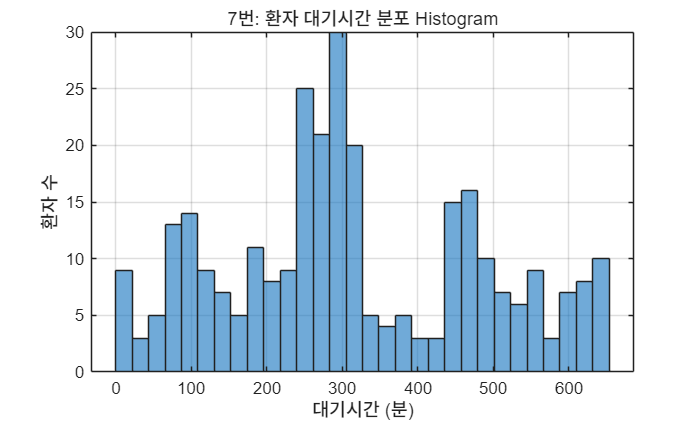


figure(8);
histogram(waiting_times, 30);
title('7번: 환자 대기시간 분포 Histogram');
xlabel('대기시간 (분)');
ylabel('환자 수');
grid on;